### Integrating gait constraints to sample gaits in a contact state

The motion planning problem is handled case by case, below.

addpath 'Data'\ 'Utility Functions'\;
load('case_1_kinematics'); load('case_1_kinematics_motionplan.mat');

#### 
$$S_{12}$$


Let's first find a way to overlay the gait constraint vector field, $d\phi$ on top of the infinitesimal disps for ease of access.

% choose the first submanifold
si = 1;
% use the kinematics computed earlier to plot the infinitesimal disps-- modify some data before based on requirement
p_info{si}.cLvl = 25; % default is 25
p_info{si}.cfLvl = 25; % default is 100
% p_info{si}.fA = 1.0; % default is 1
p_info{si}.lW_s = 2.0; % path linewidth for animations
p_info{si}.colP = [0,0,0]/255; % gait constraint contours props to aid path planning
p_info{si}.lS = ':';
S_data = {p_info{si}, p_kin{si}, kinfunc{si}};
qlevel2noslip_mp(S_data);
% obtain the vector fields you want to integrate over
[dz, dpsi, ksq, symstr] = returnVectorFields(S_data{3}, si);

Let's try to design a sub gait with a focus of x-displacement.

% initialize the arguments
ank = kinfunc{si}.ank;
a = kinfunc{si}.aa;
l = kinfunc{si}.ll;

ptf = pi/6*[1, 0] + pi/6*[0, 1];                        % point of interest ( @(-30,-30) degrees ) to integrate about
% ptf = -deg2rad(21)*[1, 0] + deg2rad(21)*[0, 1];         % point of interest ( @(-21,+21) degrees ) to integrate about
t = [1, 1];                                             % integration times in the backward and forward direction from "stpt"
dc = 0.2;                                               % percentage of time spent in the deadband
dnum = 201; S_data{3}.dnum = dnum;                      % number of points needed on the active path
dirn = 1;                                               % direction to integrate along: +1 is along +dphi and -1 is along -dphi. Everything inbetween will scale the path range.

% compute the color of the path based on gait constraints
c = interp1( linspace(p_info{si}.ksq_lim(1), p_info{si}.ksq_lim(2), size(p_info{si}.jetDark, 1)), p_info{si}.jetDark, ksq(a, l, ptf(1), ptf(2)), 'spline' );  c(c > 1) = 1;

% create a Path2 object-- get the props and call the static methods
path12 = Path2( ank, a, l, dz, dpsi, ptf, t, dc, [c; [37, 37, 37]/255], si, dirn );
Path2.compute_trajectory( path12, symstr, dnum );

Now, we are ready to plot out the paths generated.

path = path12;
S_data{4} = pltkin;
S_data{5} = path;    % add the 'pltkin' strct and 'Path2' object for plotting the animation
S_data{1}.fA = 0.70;     % make it 30% transparent to see the curvers better
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
S_data{6} = false; % true-- video, false-- no video
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
S_data{1}.skp_path = [1 20];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
S12_data_y = S_data; save('Data\case_1_S12_y.mat', 'S12_data_y');
% S12_data_xtheta = S_data; save('Data\case_1_S12_xtheta.mat', 'S12_data_xtheta');
qlevel2noslip_mp(S_data); % run the animation and plot the computed open_trajectories
exportsetupdlg;
clear S_data;

addpath 'Data'\ 'Utility Functions'\;
load('case_1_kinematics'); load('case_1_kinematics_motionplan.mat');

#### 
$$S_{34}$$


Let's create a complementary gait in the $S_{34}$ submanifold to obtain a net displacement in the y-direction.

% contact submanifold ordering from left to right: [12, 23, 34, 41, 13, 24]
si = 3; % S34
p_info{si}.cLvl = 25;
p_info{si}.cfLvl = 25;
p_info{si}.lW_s = 2.0;
p_info{si}.colP = [0,0,0]/255;
p_info{si}.lS = ':';
S_data = {p_info{si}, p_kin{si}, kinfunc{si}};
qlevel2noslip_mp(S_data);
[dz, dpsi, ksq, symstr] = returnVectorFields(S_data{3}, si);
ank = kinfunc{si}.ank;
a = kinfunc{si}.aa;
l = kinfunc{si}.ll;
ptf = pi/6*[+1, 0] + pi/6*[0, +1]; % pof = (+30,+30) degrees
% ptf = -1*deg2rad(21)*[+1, 0] + +1*deg2rad(21)*[0, +1]; % pof = (-21,+21) degrees
t = [1, 1];
dc = 0.2;
dnum = 201; S_data{3}.dnum = dnum; 
dirn = -1; % +1 %-1
% dirn = 1;
c = interp1( linspace(p_info{si}.ksq_lim(1), p_info{si}.ksq_lim(2), size(p_info{si}.jetDark, 1)), p_info{si}.jetDark, ksq(a, l, ptf(1), ptf(2)), 'spline' );  c(c > 1) = 1;
path34 = Path2( ank, a, l, dz, dpsi, ptf, t, dc, [c; [37, 37, 37]/255], si, dirn );
Path2.compute_trajectory( path34, symstr, dnum );
path = path34;
S_data{4} = pltkin;
S_data{5} = path;
S_data{1}.fA = 0.70;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
S_data{6} = false; % true-- video, false-- no video
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
S_data{1}.skp_path = [1 20];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
S34_data_y = S_data; save('Data\case_1_S34_y.mat', 'S34_data_y');
% S34_data_mxtheta = S_data; save('Data\case_1_S34_mxtheta.mat', 'S34_data_mxtheta');
qlevel2noslip_mp(S_data); 
exportsetupdlg;
clear S_data;

Now, we can combine these paths to generate a 2-beat gait for the quadrupedal robot.

addpath 'Data'\ 'Utility Functions'\;
load('case_1_kinematics'); load('case_1_kinematics_motionplan.mat');
load('Data\case_1_S12_y.mat'); load('Data\case_1_S12_xtheta.mat'); load('Data\case_1_S34_mxtheta.mat'); load('Data\case_1_S34_y.mat');

#### 
$$S_{12} \leftrightarrow S_{34}$$


In this simple 2-beat gait, we start with the first path we generated in $S_{12}$ and then switch to the path in $S_{34}$. Recall that each of these paths have a scaling factor associated with scales the paths about a certain point of interest. Let's call them $u_\psi$ for the path's they are associated with. Then the 2-beat gait can be defined as the overlap between the shape-space slices in each of these paths. We need to complete these paths in a special certain way so that their active regions don't overlap, then we can express the 2-beat gait and the corresponding net displacement as shown below,


$$\phi_{i j} = \psi_i \, u_i + \psi_j \, u_j, \,\, u \in (-1, 1) \cap \mathbb{R} \\
z^{\phi_{i j}} = z^{\psi_i \, u_i} + z^{\psi_j \, u_j}$$


% % % % %           |
% % % % %    -,+    |   +,+
% % % % % ----------------------
% % % % %    -,-    |   +,-
% % % % %           |
% % % % % shown above is how the gaits can be combined since ui and uj can range between (-1, 1), we are looking at the unit square for generating a bound-like gait.
% % % % % to plot the video, let's give an input to each path in 10s of percentages-- for instance, -10% for path 1 and 50% for path 2.
dataij = [];
dataij.vidF = true; % true % false
dataij.u = [+100, +100]/100; % y-path
% dataij.u = [+100, -100]/100; % x-path
% dataij.gaitC_num = 1; % just for theta path
% dataij.u = [+100, +100]/100;
S12_data_y{1}.fA = 0.7;
S34_data_y{1}.fA = 0.7;
dataij = qlevel2noslip_mp(S12_data_y, S34_data_y, dataij);
plotnetdispofnoslip2bgaits(S12_data_y, S34_data_y, dataij);
save('Data\case_1_S12toS34_y_gait.mat','dataij');
% S12_data_xtheta{1}.fA = 0.7;
% S34_data_mxtheta{1}.fA = 0.7;
% dataij = qlevel2noslip_mp(S12_data_xtheta, S34_data_mxtheta, dataij);
% plotnetdispofnoslip2bgaits(S12_data_xtheta, S34_data_mxtheta, dataij);
% save('Data\case_1_S12toS34_xy_gait.mat','dataij');
% S12_data_xtheta{1}.fA = 0.7;
% S34_data_mxtheta{1}.fA = 0.7;
% dataij = qlevel2noslip_mp(S12_data_xtheta, S34_data_mxtheta, dataij);
% plotnetdispofnoslip2bgaits(S12_data_xtheta, S34_data_mxtheta, dataij);
% save('Data\case_1_S12toS34_theta_gait.mat','dataij');

#### 
$$S_{23}$$


Need paths in y and xtheta directions.

% contact submanifold ordering from left to right: [12, 23, 34, 41, 13, 24]
si = 2; % S23
p_info{si}.cLvl = 25;
p_info{si}.cfLvl = 25;
p_info{si}.lW_s = 2.0;
p_info{si}.colP = [0,0,0]/255;
p_info{si}.lS = ':';
S_data = {p_info{si}, p_kin{si}, kinfunc{si}};
qlevel2noslip_mp(S_data);
[dz, dpsi, ksq, symstr] = returnVectorFields(S_data{3}, si);
ank = kinfunc{si}.ank;
a = kinfunc{si}.aa;
l = kinfunc{si}.ll;
%%%%%%%%%%%%%%%%%%%%%%%%%
ptf = 0*[+1, 0] + 0*[0, +1];                                   % pof = (+0,+0) degrees % y path
% ptf = -0.707106781186548*[+1, 0] + -0.707106781186548*[0, +1]; 
% ptf = -deg2rad(18)*[+1, 0] + deg2rad(18)*[0, +1];
%%%%%%%%%%%%%%%%%%%%%%%%%
t = [1, 1];
dc = 0.2;
dnum = 201; S_data{3}.dnum = dnum; 
%%%%%%%%%%%%%%%%%%%%%%%%%
dirn = 1;
% dirn = 1;
% dirn = -1;
%%%%%%%%%%%%%%%%%%%%%%%%%
c = interp1( linspace(p_info{si}.ksq_lim(1), p_info{si}.ksq_lim(2), size(p_info{si}.jetDark, 1)), p_info{si}.jetDark, ksq(a, l, ptf(1), ptf(2)), 'spline' ); c(c > 1) = 1;
path23 = Path2( ank, a, l, dz, dpsi, ptf, t, dc, [c; [37, 37, 37]/255], si, dirn );
Path2.compute_trajectory( path23, symstr, dnum );
path = path23;
S_data{4} = pltkin;
S_data{5} = path;
S_data{1}.fA = 0.70;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
S_data{6} = false; % true-- video, false-- no video
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
S_data{1}.skp_path = [1 20];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
qlevel2noslip_mp(S_data);
exportsetupdlg;
S23_data_y = S_data; save('Data\case_1_S23_y.mat', 'S23_data_y'); % , '-append'
% S23_data_xy = S_data; save('Data\case_1_S23_xy.mat', 'S23_data_xy'); % , '-append'
% S23_data_mytheta = S_data; save('Data\case_1_S23_mytheta.mat', 'S23_data_mytheta'); % , '-append'

addpath 'Data'\ 'Utility Functions'\;
load('case_1_kinematics'); load('case_1_kinematics_motionplan.mat');

#### 
$$S_{41}$$


% contact submanifold ordering from left to right: [12, 23, 34, 41, 13, 24]
si = 4; % S23
p_info{si}.cLvl = 25;
p_info{si}.cfLvl = 25;
p_info{si}.lW_s = 2.0;
p_info{si}.colP = [0,0,0]/255;
p_info{si}.lS = ':';
S_data = {p_info{si}, p_kin{si}, kinfunc{si}};
qlevel2noslip_mp(S_data);
[dz, dpsi, ksq, symstr] = returnVectorFields(S_data{3}, si);
ank = kinfunc{si}.ank;
a = kinfunc{si}.aa;
l = kinfunc{si}.ll;
%%%%%%%%%%%%%%%%%%%%%%%%%
ptf = 0*[+1, 0] + 0*[0, +1];                                  % pof = (+0,+0) degrees % y path
% ptf = +0.707106781186548*[+1, 0] + +0.707106781186548*[0, +1]; 
% ptf = -deg2rad(18)*[+1, 0] + deg2rad(18)*[0, +1];
%%%%%%%%%%%%%%%%%%%%%%%%%
t = [1, 1];
dc = 0.2;
dnum = 201; S_data{3}.dnum = dnum; 
%%%%%%%%%%%%%%%%%%%%%%%%%
dirn = -1;
% dirn = +1;
% dirn = -1;
%%%%%%%%%%%%%%%%%%%%%%%%%
c = interp1( linspace(p_info{si}.ksq_lim(1), p_info{si}.ksq_lim(2), size(p_info{si}.jetDark, 1)), p_info{si}.jetDark, ksq(a, l, ptf(1), ptf(2)), 'spline' ); c(c > 1) = 1;
path23 = Path2( ank, a, l, dz, dpsi, ptf, t, dc, [c; [37, 37, 37]/255], si, dirn );
Path2.compute_trajectory( path23, symstr, dnum );
path = path23;
S_data{4} = pltkin;
S_data{5} = path;
S_data{1}.fA = 0.70;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
S_data{6} = false; % true-- video, false-- no video
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
S_data{1}.skp_path = [1 20];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
qlevel2noslip_mp(S_data);
exportsetupdlg;
S41_data_y = S_data; save('Data\case_1_S41_y.mat', 'S41_data_y'); % , '-append'
% S41_data_xmy = S_data; save('Data\case_1_S41_xmy.mat', 'S41_data_xmy'); % , '-append'
% S41_data_ytheta = S_data; save('Data\case_1_S41_ytheta.mat', 'S41_data_ytheta'); % , '-append'

addpath 'Data'\ 'Utility Functions'\;
load('case_1_kinematics'); load('case_1_kinematics_motionplan.mat');
load('Data\case_1_S23_y.mat'); load('Data\case_1_S23_xy.mat'); load('Data\case_1_S23_mytheta.mat');
load('Data\case_1_S41_y.mat'); load('Data\case_1_S41_xmy.mat'); load('Data\case_1_S41_ytheta.mat');

#### 
$$S_{23} \leftrightarrow S_{41}$$


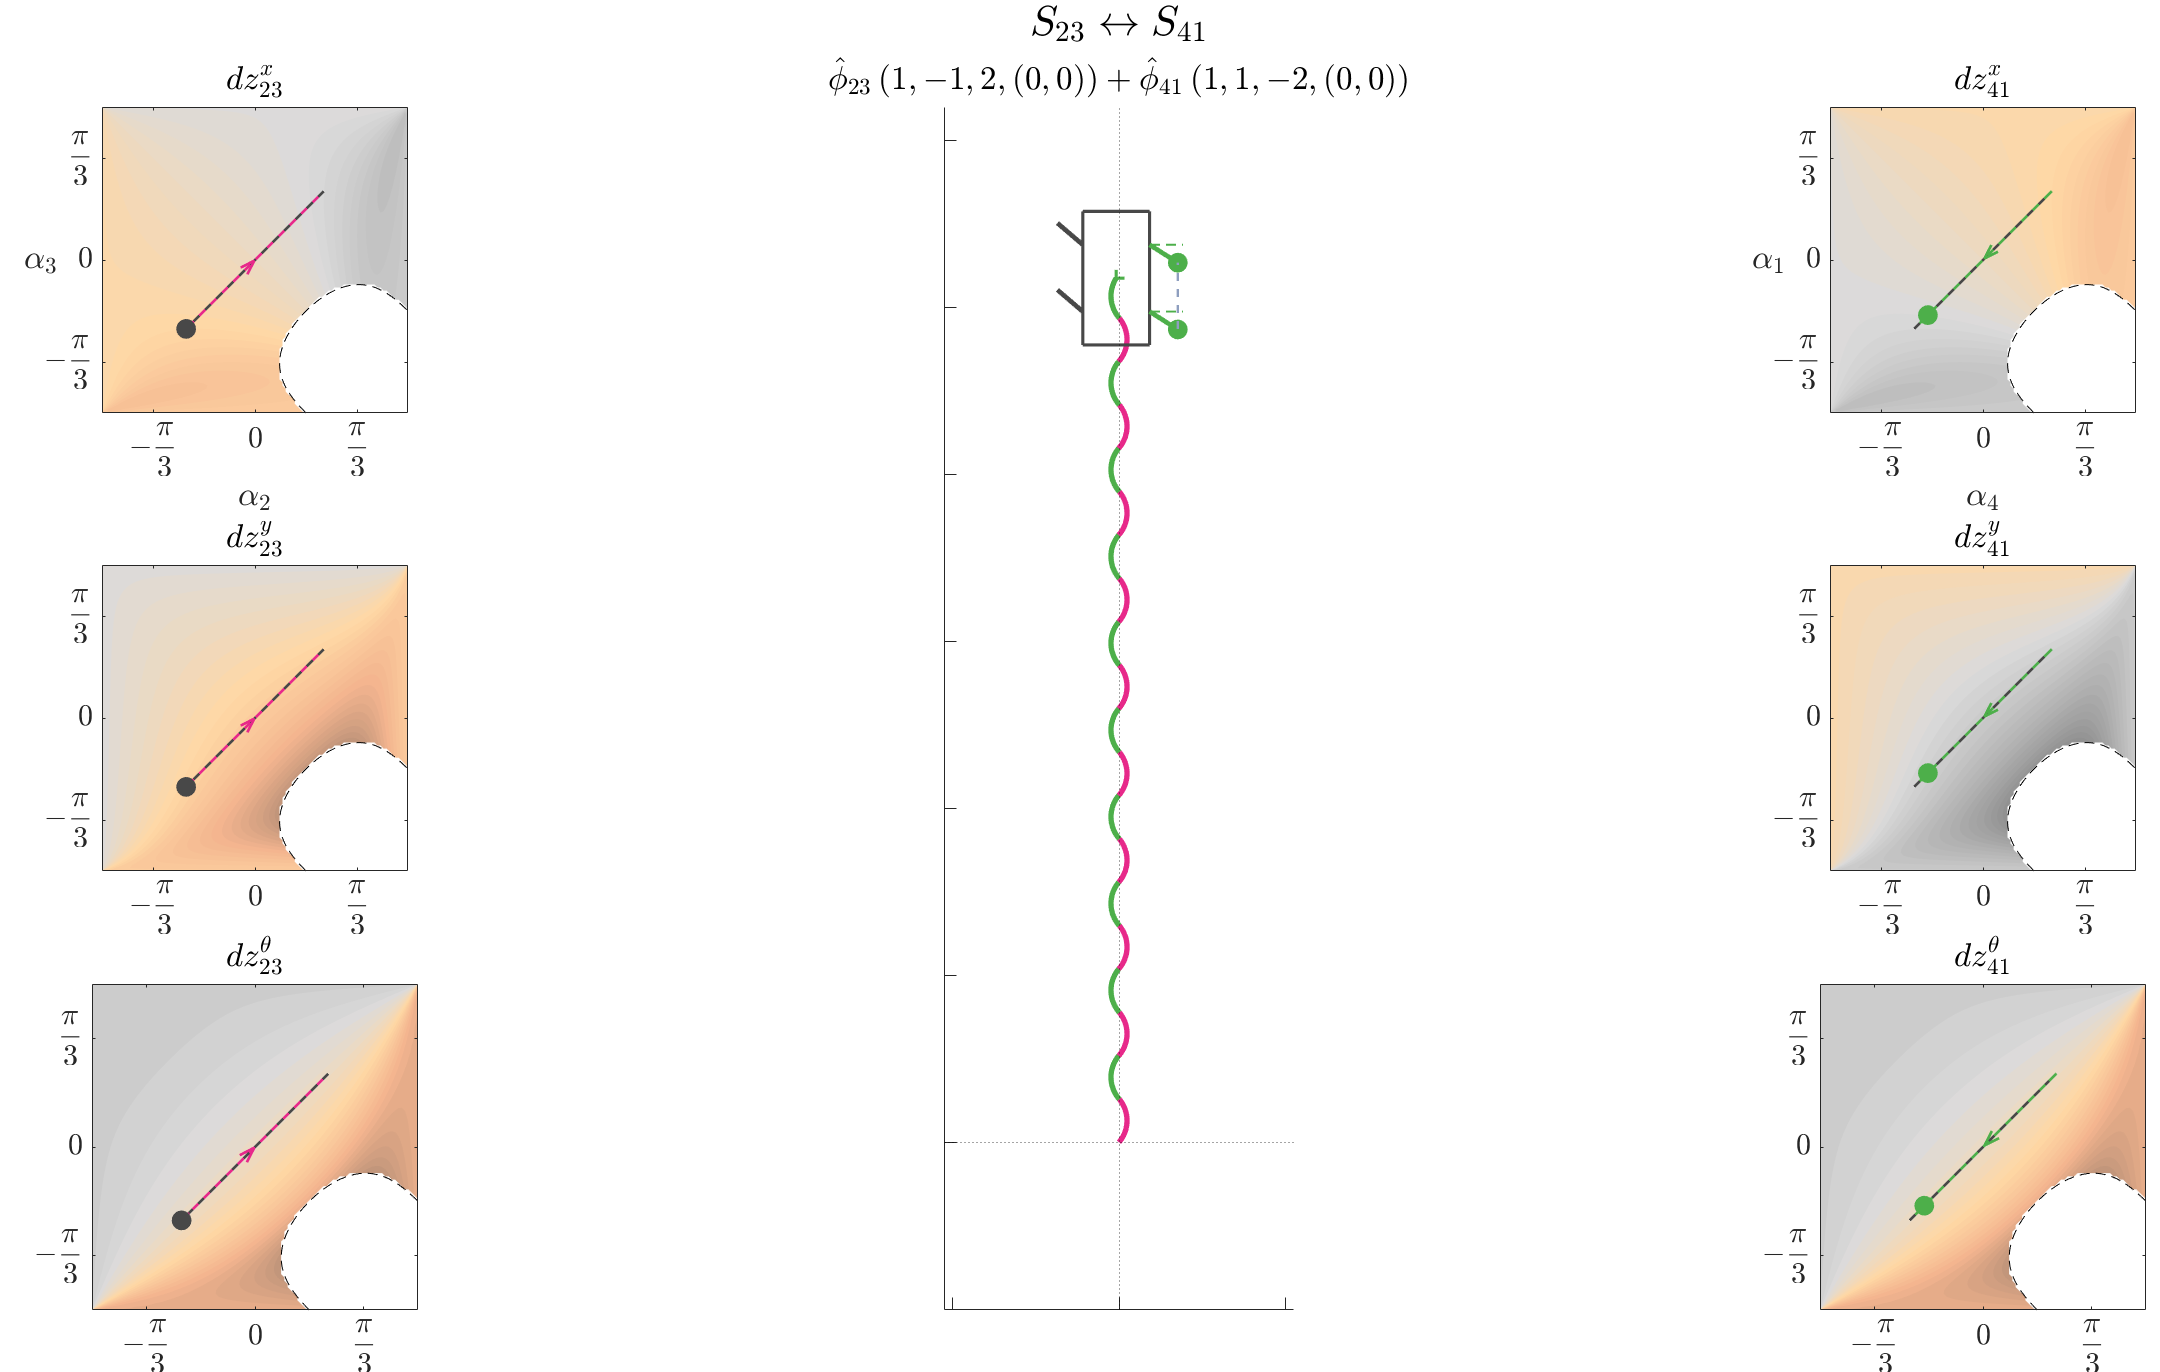

dataij = [];
dataij.vidF = true; % true % false
dataij.u = [+100, +100]/100; % y path
% dataij.u = [+100, +100]/100; % x path
% dataij.u = [+100, -100]/100; % y path 2.0
% dataij.gaitC_num = 1; % just for theta path
% dataij.u = [+100, +100]/100; % theta path
% dataij.u = [-100, +100]/100; % y path 3.0
S23_data_y{1}.fA = 0.7;
S41_data_y{1}.fA = 0.7;
dataij = qlevel2noslip_mp(S23_data_y, S41_data_y, dataij);

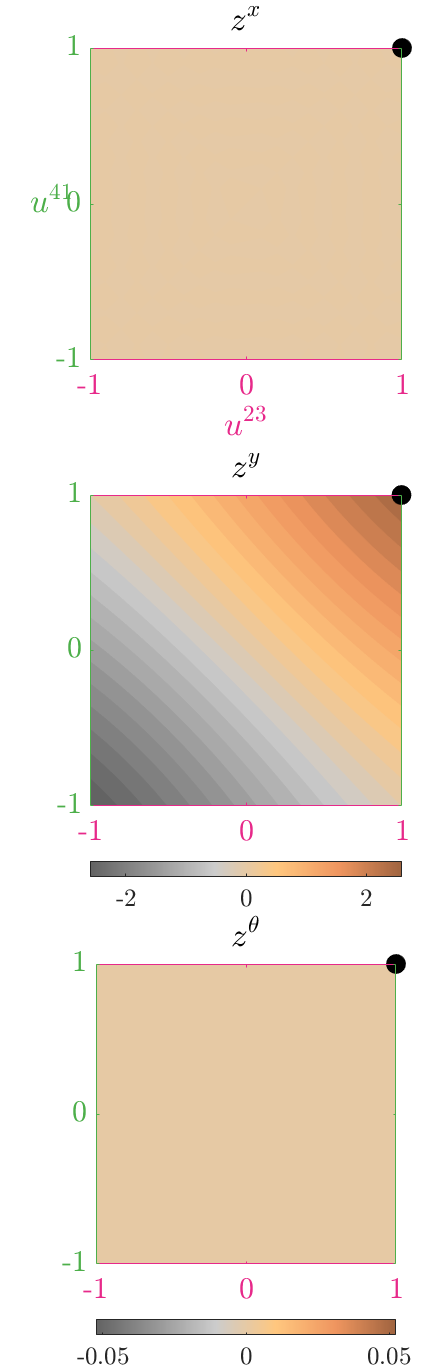

plotnetdispofnoslip2bgaits(S23_data_y, S41_data_y, dataij);

save('Data\case_1_S23toS41_y_gait.mat','dataij');
% S23_data_xy{1}.fA = 0.7;
% S41_data_xmy{1}.fA = 0.7;
% dataij = qlevel2noslip_mp(S23_data_xy, S41_data_xmy, dataij);
% plotnetdispofnoslip2bgaits(S23_data_xy, S41_data_xmy, dataij);
% save('Data\case_1_S23toS41_x_gait.mat','dataij');
% S23_data_xy{1}.fA = 0.7;
% S41_data_xmy{1}.fA = 0.7;
% dataij = qlevel2noslip_mp(S23_data_xy, S41_data_xmy, dataij);
% plotnetdispofnoslip2bgaits(S23_data_xy, S41_data_xmy, dataij);
% save('Data\case_1_S23toS41_y_gait_2.mat','dataij');
% S23_data_mytheta{1}.fA = 0.7;
% S41_data_ytheta{1}.fA = 0.7;
% dataij = qlevel2noslip_mp(S23_data_mytheta, S41_data_ytheta, dataij);
% plotnetdispofnoslip2bgaits(S23_data_mytheta, S41_data_ytheta, dataij);
% save('Data\case_1_S23toS41_theta_gait.mat','dataij');
% S23_data_mytheta{1}.fA = 0.7;
% S41_data_ytheta{1}.fA = 0.7;
% dataij = qlevel2noslip_mp(S23_data_mytheta, S41_data_ytheta, dataij);
% plotnetdispofnoslip2bgaits(S23_data_mytheta, S41_data_ytheta, dataij);
% save('Data\case_1_S23toS41_y_gait_3.mat','dataij');

addpath 'Data'\ 'Utility Functions'\;
load('case_1_kinematics'); load('case_1_kinematics_motionplan.mat');

#### 
$$S_{13}$$


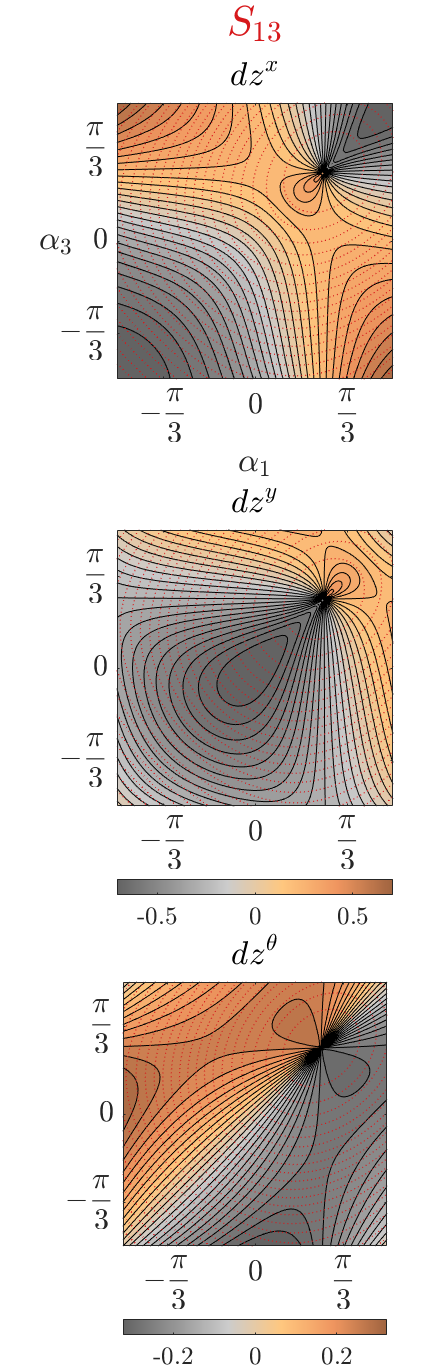

% contact submanifold ordering from left to right: [12, 23, 34, 41, 13, 24]
si = 5; % S13
p_info{si}.cLvl = 25;
p_info{si}.cfLvl = 25;
p_info{si}.lW_s = 2.0;
p_info{si}.colP = [0,0,0]/255;
p_info{si}.lS = ':';
S_data = {p_info{si}, p_kin{si}, kinfunc{si}};
qlevel2noslip_mp(S_data);

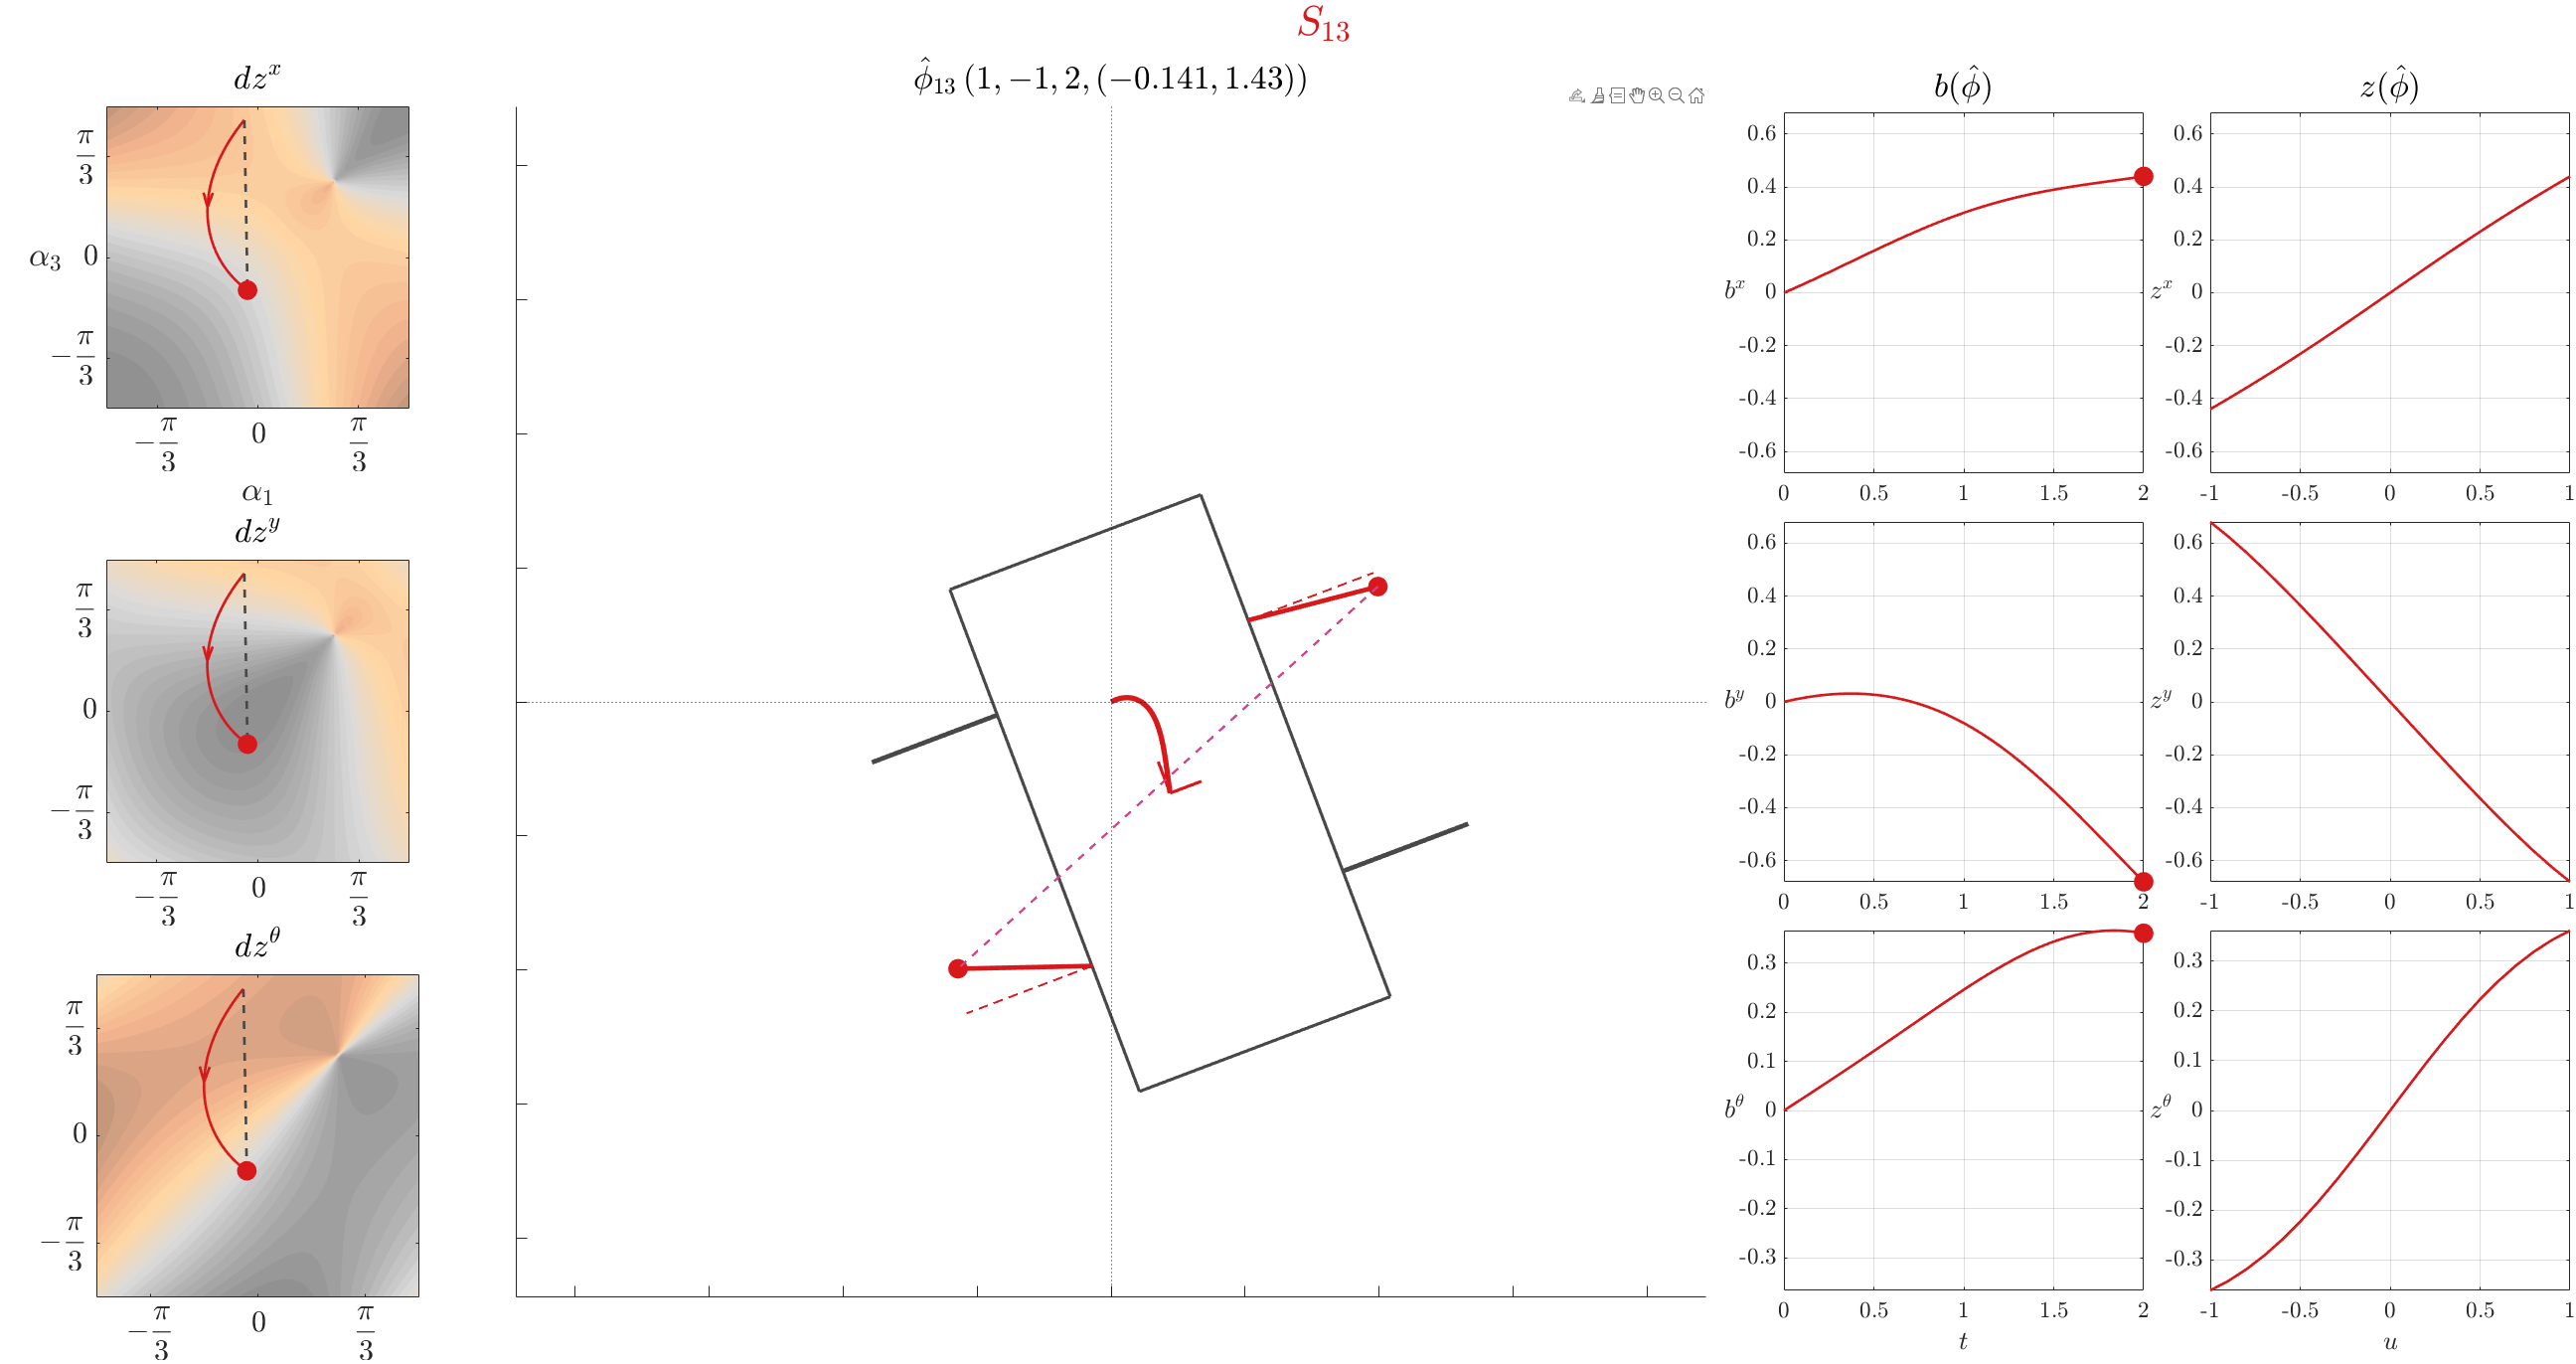

[dz, dpsi, ksq, symstr] = returnVectorFields(S_data{3}, si);
ank = kinfunc{si}.ank;
a = kinfunc{si}.aa;
l = kinfunc{si}.ll;
%%%%%%%%%%%%%%%%%%%%%%%%%
% ptf = 0*[+1, 0] + 0*[0, +1]; % y path
ptf = -(pi/6)*[+1, 0] + (pi/6)*[0, +1]; % theta path
%%%%%%%%%%%%%%%%%%%%%%%%%
t = [1, 1];
dc = 0.2;
dnum = 201; S_data{3}.dnum = dnum; 
%%%%%%%%%%%%%%%%%%%%%%%%%
% dirn = -1;
dirn = +1;
%%%%%%%%%%%%%%%%%%%%%%%%%
c = interp1( linspace(p_info{si}.ksq_lim(1), p_info{si}.ksq_lim(2), size(p_info{si}.jetDark, 1)), p_info{si}.jetDark, ksq(a, l, ptf(1), ptf(2)), 'spline' ); c(c > 1) = 1;
path13 = Path2( ank, a, l, dz, dpsi, ptf, t, dc, [c; [37, 37, 37]/255], si, dirn );
Path2.compute_trajectory( path13, symstr, dnum );
path = path13;
S_data{4} = pltkin;
S_data{5} = path;
S_data{1}.fA = 0.70;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
S_data{6} = false; % true-- video, false-- no video
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
S_data{1}.skp_path = [1 20];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
qlevel2noslip_mp(S_data);

% exportsetupdlg;
% S13_data_mxy = S_data; save('Data\case_1_S13_mxy.mat', 'S13_data_mxy');
S13_data_xmytheta = S_data; save('Data\case_1_S13_xmytheta.mat', 'S13_data_xmytheta');

addpath 'Data'\ 'Utility Functions'\;
load('case_1_kinematics'); load('case_1_kinematics_motionplan.mat');

#### 
$$S_{24}$$


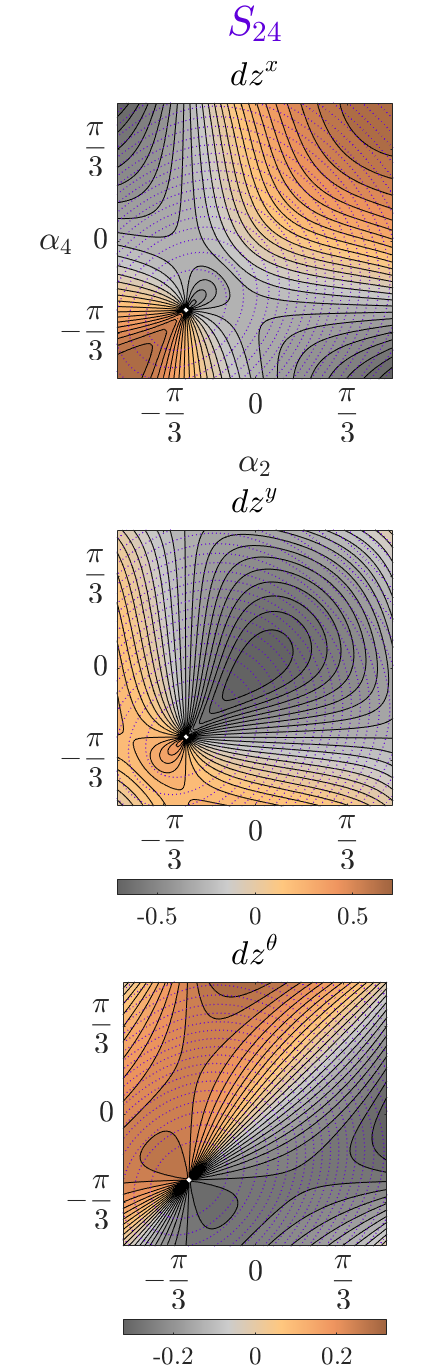

% contact submanifold ordering from left to right: [12, 23, 34, 41, 13, 24]
si = 6; % S24
p_info{si}.cLvl = 25;
p_info{si}.cfLvl = 25;
p_info{si}.lW_s = 2.0;
p_info{si}.colP = [0,0,0]/255;
p_info{si}.lS = ':';
S_data = {p_info{si}, p_kin{si}, kinfunc{si}};
qlevel2noslip_mp(S_data);

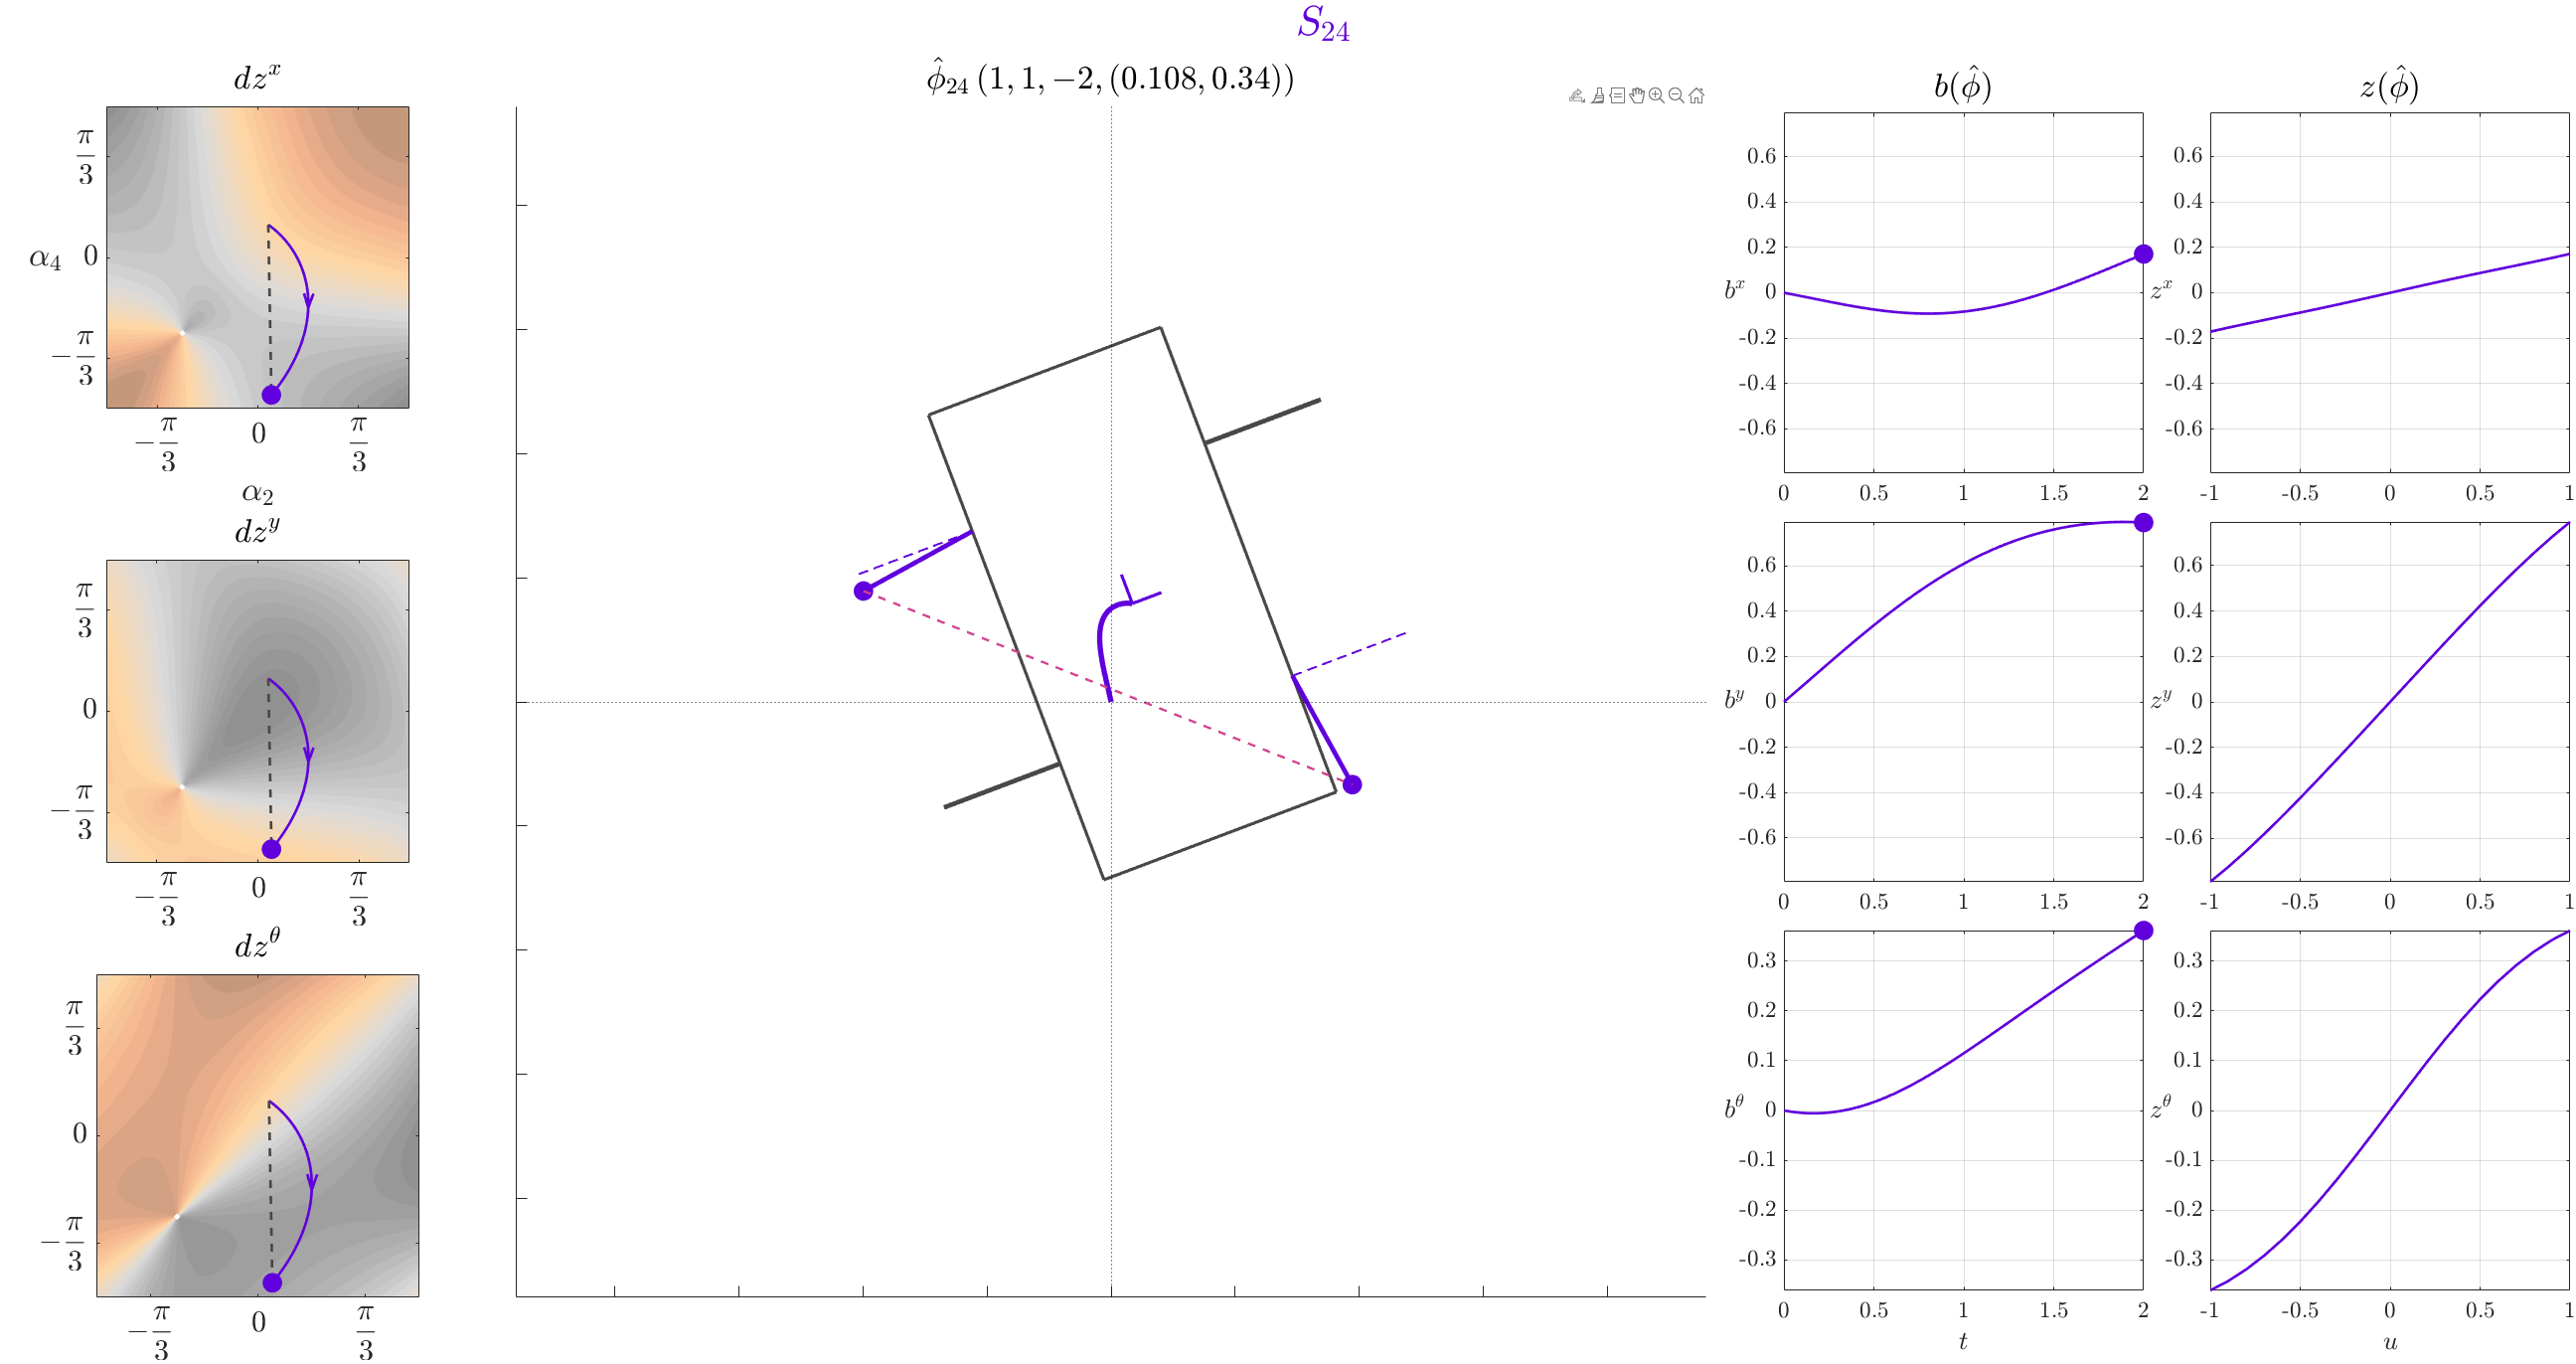

[dz, dpsi, ksq, symstr] = returnVectorFields(S_data{3}, si);
ank = kinfunc{si}.ank;
a = kinfunc{si}.aa;
l = kinfunc{si}.ll;
%%%%%%%%%%%%%%%%%%%%%%%%%
% ptf = 0*[+1, 0] + 0*[0, +1]; % y path
ptf = (pi/6)*[+1, 0] + -(pi/6)*[0, +1]; % theta path
%%%%%%%%%%%%%%%%%%%%%%%%%
t = [1, 1];
dc = 0.2;
dnum = 201; S_data{3}.dnum = dnum; 
%%%%%%%%%%%%%%%%%%%%%%%%%
% dirn = -1;
dirn = -1;
%%%%%%%%%%%%%%%%%%%%%%%%%
c = interp1( linspace(p_info{si}.ksq_lim(1), p_info{si}.ksq_lim(2), size(p_info{si}.jetDark, 1)), p_info{si}.jetDark, ksq(a, l, ptf(1), ptf(2)), 'spline' ); c(c > 1) = 1;
path24 = Path2( ank, a, l, dz, dpsi, ptf, t, dc, [c; [37, 37, 37]/255], si, dirn );
Path2.compute_trajectory( path24, symstr, dnum );
path = path24;
S_data{4} = pltkin;
S_data{5} = path;
S_data{1}.fA = 0.70;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
S_data{6} = false; % true-- video, false-- no video
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
S_data{1}.skp_path = [1 20];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
qlevel2noslip_mp(S_data);

% exportsetupdlg;
% S24_data_xy = S_data; save('Data\case_1_S24_xy.mat', 'S24_data_xy');
S24_data_xytheta = S_data; save('Data\case_1_S24_xytheta.mat', 'S24_data_xytheta');

addpath 'Data'\ 'Utility Functions'\;
load('case_1_kinematics'); load('case_1_kinematics_motionplan.mat');
load('Data\case_1_S13_mxy.mat'); 
load('Data\case_1_S13_xmytheta.mat');
load('Data\case_1_S24_xy.mat'); 
load('Data\case_1_S24_xytheta.mat');

#### 
$$S_{13} \leftrightarrow S_{24}$$


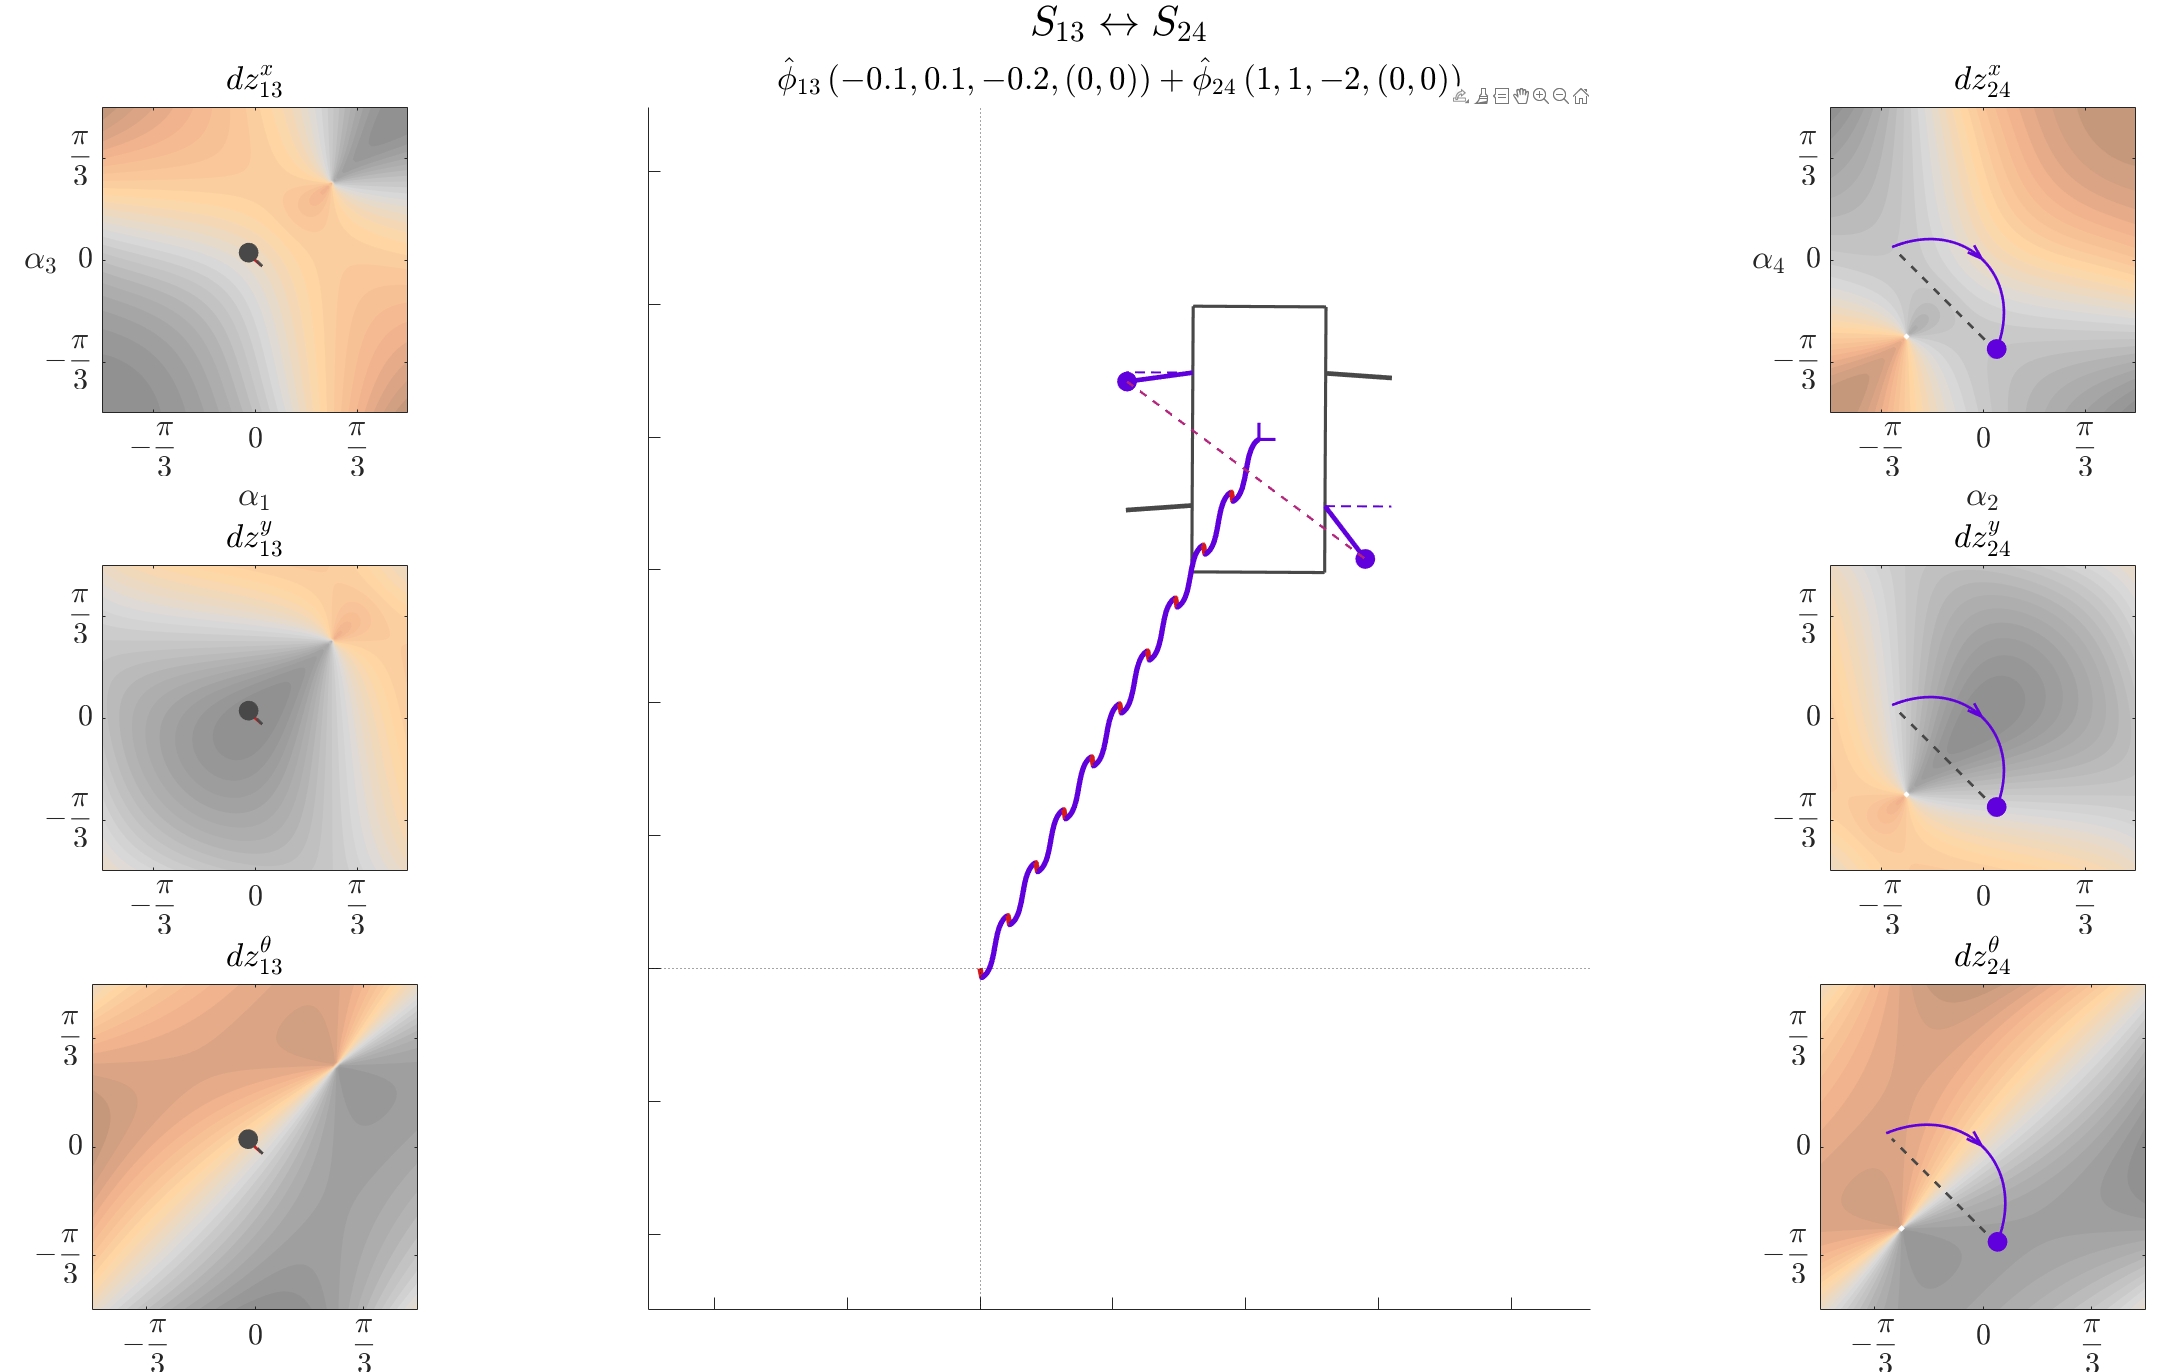

dataij = [];
dataij.vidF = false; % true % false
% dataij.u = [+100, +100]/100; % y path
% dataij.gaitC_num = 1; % just for theta path
% dataij.u = [+100, +100]/100; % theta path
% dataij.u = [-100, +100]/100; % x path
dataij.u = [-10, +100]/100;
% S13_data_mxy{1}.fA = 0.7;
% S24_data_xy{1}.fA = 0.7;
% dataij = qlevel2noslip_mp(S13_data_mxy, S24_data_xy, dataij);
% plotnetdispofnoslip2bgaits(S13_data_mxy, S24_data_xy, dataij);
% save('Data\case_1_S13toS24_y_path.mat','dataij');
% S13_data_xmytheta{1}.fA = 0.7;
% S24_data_xytheta{1}.fA = 0.7;
% dataij = qlevel2noslip_mp(S13_data_xmytheta, S24_data_xytheta, dataij);
% plotnetdispofnoslip2bgaits(S13_data_xmytheta, S24_data_xytheta, dataij);
% save('Data\case_1_S13toS24_theta_path.mat','dataij');
% S13_data_mxy{1}.fA = 0.7;
% S24_data_xy{1}.fA = 0.7;
% dataij = qlevel2noslip_mp(S13_data_mxy, S24_data_xy, dataij);
% plotnetdispofnoslip2bgaits(S13_data_mxy, S24_data_xy, dataij);
% save('Data\case_1_S13toS24_x_path.mat','dataij');
S13_data_mxy{1}.fA = 0.7;
S24_data_xy{1}.fA = 0.7;
dataij = qlevel2noslip_mp(S13_data_mxy, S24_data_xy, dataij);

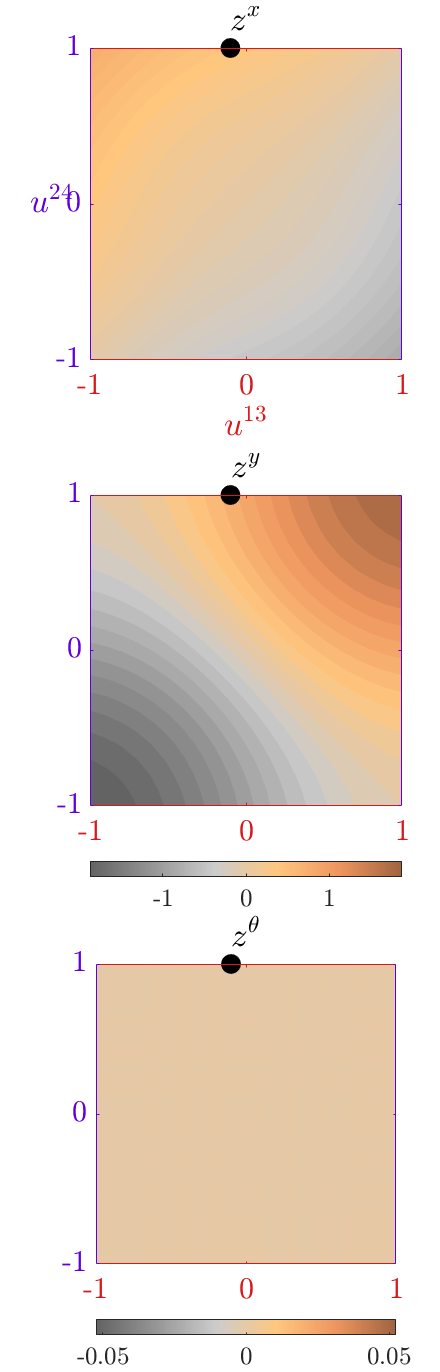

plotnetdispofnoslip2bgaits(S13_data_mxy, S24_data_xy, dataij);

save('Data\case_1_S13toS24_test_path.mat','dataij');

addpath 'Data'\ 'Utility Functions'\;
load('case_1_kinematics'); load('case_1_kinematics_motionplan.mat');

## Conservativity of the Kinematics

In this section, we shall explore the conservative nature of the local connection with two sequential paths. The first path satisfies the no-slip gait constraint and the second path starts at the end of the first path and returns to the initial.

% % % load('Data\case_1_S12_y.mat'); si = 1;
% % % 
% % % % Get the +50% path; we won't use the full path since the connecting path passes through the robot singularity.
% % % ic = S12_data_y{5}.initial_condition{15};
% % % fc = S12_data_y{5}.final_condition{15};
% % % path_1 = S12_data_y{5}.open_trajectory{15};
% % % zx = S12_data_y{5}.net_displacement(1,15);
% % % zy = S12_data_y{5}.net_displacement(2,15);
% % % ztheta = S12_data_y{5}.net_displacement(3,15);
% % % 
% % % % compute the second path from the end of the first path back to the initial condition of the first path
% % % delt = path_1{1}(end);
% % % deli = ic(1) - fc(1); slopei = deli/delt;
% % % delj = ic(2) - fc(2); slopej = delj/delt;
% % % syms a l t x y theta alpha_1 alpha_2 real
% % % ai_0 = fc(1); aj_0 = fc(2);
% % % dz_path_2 = matlabFunction(simplify([-TeLg_old(ztheta)*A_1_12(:,1:2); eye(2,2)]*[slopei; slopej], 'Steps', 10), 'Vars', [a l t x y theta alpha_1 alpha_2]);
% % % [tf, qf] = ode45( @(t,y) dz_path_2(1, 1, t, y(1), y(2), y(3), y(4), y(5)), path_1{1}, [zx; zy; ztheta; fc(1); fc(2)] );
% % % path_2 = cell(size(path_1));
% % % path_2{1} = tf(:)';
% % % path_2{2} = qf(:,1)';
% % % path_2{3} = qf(:,2)';
% % % path_2{4} = qf(:,3)';
% % % path_2{5} = qf(:,4)';
% % % path_2{6} = qf(:,5)';

Let's plot the translation trajectory to see how the system behaves,

% % % figure()
% % % plot(path_1{2}, path_1{3}, 'r', 'LineWidth', 1.2);
% % % hold on; grid on; axis equal square;
% % % plot(path_2{2}, path_2{3}, 'r--', 'LineWidth', 1.2);
% % % axis([-1 1 -1 1]);

Not exactly conservative-- this will be point of exploration for future work.